## Initialisation du simulink : Methode Pur Pursuit

### On defini les variables

#### Constantes

v = 5 % vitesse constante (m/s)

v = 5

L = 2 % distance entre les roues avant et arrieres (m)

L = 2


T = 5*60 % Temps de simulation (s)

T = 300

Te = 0.01 % Temps d'echantillonage (s)

Te = 0.0100

#### Variables

Initialisation à 0 pour toutes les variables

psi = pi/2 %Yaw

psi = 1.5708

x = 0 % coordonnées du centre de gravité de la voiture

x = 0

y = 0

y = 0

Pour l'instant le chemin a suivre est un sin

Xg = 0:Te:T

Xg =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


Yg = 100 * cos(Xg*0.1)

Yg =   100.0000  100.0000   99.9998   99.9996   99.9992   99.9988   99.9982   99.9976   99.9968   99.9960   99.9950   99.9940   99.9928   99.9916   99.9902   99.9888   99.9872   99.9856   99.9838   99.9820   99.9800   99.9780   99.9758   99.9736   99.9712   99.9688   99.9662   99.9636   99.9608   99.9580   99.9550   99.9520   99.9488   99.9456   99.9422   99.9388   99.9352   99.9316   99.9278   99.9240   99.9200   99.9160   99.9118   99.9076   99.9032   99.8988   99.8942   99.8896   99.8848   99.8800



Xg_sim.time = Xg';
Xg_sim.signals.values = Xg';

Yg_sim.time = Xg';
Yg_sim.signals.values = Yg';

xg = Xg(1)

xg = 0

yg = Yg(1)

yg = 100

#### Pur Pursuit

d=3 %Lookahead distance

d = 3

test

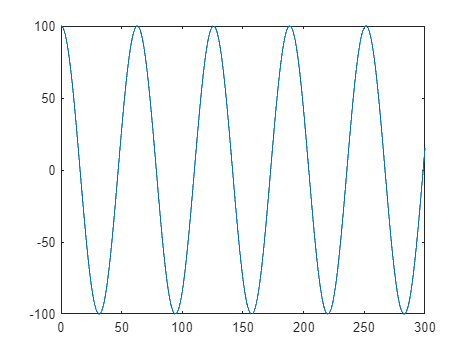

plot(Xg,Yg)

## Run Simulink

open_system('Pur_Pursuit.slx')